# Loading Data

clc;clear;
%amputation on the left side
load('G:\.shortcut-targets-by-id\1YXV-SWkwjUwCHF0E-UodEuhZKomSyoO0\SU21_Collaboration\Full Gait Simscape\kinematic_data\TF19\Matlab Workspace\TF19_DATA.mat');

# TF19 Model Set Up Variables

%Body
L = TF19.info.height*1E-2; %(31.4e-2)/(0.530-0.285); %Length of subject femur 31.4 cm Segment is (0.53H - 0.285H)
M = TF19.info.weight;
d = .005;

%Hat
hatLength = (0.818-0.530)*L;
hatMass = 0.678*M;
hatCoG = 0.5*hatLength - 0.626*hatLength;
hatRoG = 0.496*hatLength;
hatInertia = hatMass*hatRoG^2;

%Thigh
thighLength = (0.530-0.285)*L;
thighMass = 0.100*M;
thighCoG = 0.5*thighLength - 0.433*thighLength;
thighRoG = 0.323*thighLength;
thighInertia = thighMass*thighRoG^2;

%Shank/leg
shankLength = (0.285-0.039)*L;
shankMass = 0.0465*M;
shankCoG = 0.5*shankLength - 0.433*shankLength;
shankRoG = 0.302*shankLength;
shankInertia = shankMass*shankRoG^2;

%Foot
footHeight = 0.039*L;
footLength = 0.152*L;
footMass = 0.0145*M;
footCoG_x = 0.0304*L;
footCoG_y = 0.0195*L;
footRoG = 0.475*footHeight;
footInertia = footMass*footRoG^2;

%hip natural height
floor = 0.530*L;
%floor spring damper specs
k_floor = 2.646944052407765e+03;%1.5e4/4;
c_floor = 62.818842931179454;%1500/2;

## Looking at exporting TF19 Data

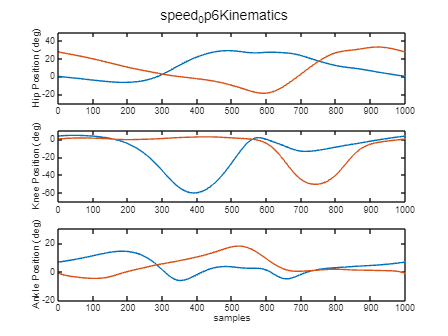

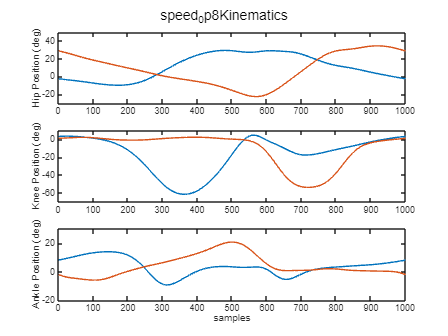

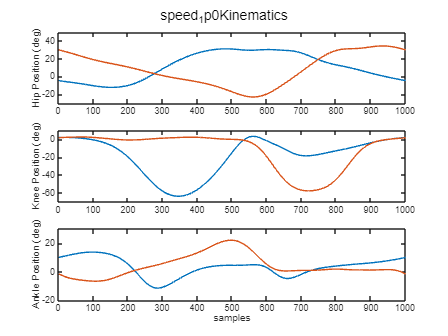

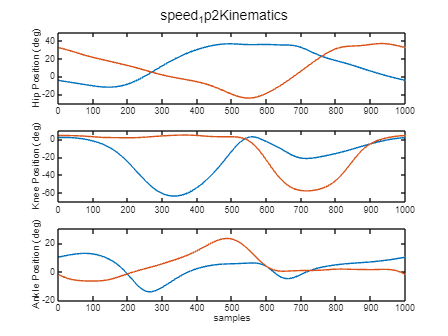

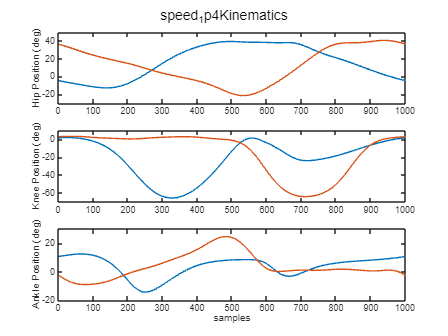

fields = fieldnames(TF19.data);
for i = 1:length(fields)
    %Have to create phase shift between right and left side, used 600 for
    %~60%, 
    %ankle
    lAnklePose(:,i) = TF19.data.(fields{i}).ipsilateral.ankle.position.avg;
    rAnklePose(:,i) = circshift(TF19.data.(fields{i}).contralateral.ankle.position.avg,600);
    %knee
    lKneePose(:,i) = TF19.data.(fields{i}).ipsilateral.knee.position.avg;
    rKneePose(:,i) = circshift(TF19.data.(fields{i}).contralateral.knee.position.avg,600);
    %hip
    lHipPose(:,i) = TF19.data.(fields{i}).ipsilateral.hip.position.avg;
    rHipPose(:,i) = circshift(TF19.data.(fields{i}).contralateral.hip.position.avg,600);

    % 1st derivatives
    %ankle
    lAnkleVel(:,i) = lAnklePose(2:end,i) - lAnklePose(1:end-1,i);
    rAnkleVel(:,i) = rAnklePose(2:end,i) - rAnklePose(1:end-1,i);
    %knee
    lKneeVel(:,i) = lKneePose(2:end,i) - lKneePose(1:end-1,i);
    rKneeVel(:,i) = rKneePose(2:end,i) - rKneePose(1:end-1,i);
    %hip
    lHipVel(:,i) = lHipPose(2:end,i) - lHipPose(1:end-1,i);
    rHipVel(:,i) = rHipPose(2:end,i) - rHipPose(1:end-1,i);

    %plots
    figure; sgtitle([fields{i} 'Kinematics']);
    subplot(3,1,1); plot(rHipPose(:,i)); hold on;  plot(lHipPose(:,i)); 
    ylabel('Hip Position (deg)'); xlim([0,1001]); ylim([-30,50]);
    % subplot(3,1,2); plot(rHipVel(:,i)); hold on;  
    % plot(lHipVel(:,i));  ylabel('Hip Vel deg/sample');
    subplot(3,1,2); plot(rKneePose(:,i)); hold on;  plot(lKneePose(:,i)); 
    ylabel('Knee Position (deg)'); xlim([0,1001]); ylim([-70,10]);
    % subplot(3,2,4); plot(rKneeVel(:,i)); hold on;  
    % plot(lKneeVel(:,i));  ylabel('Knee Vel deg/sample');
    subplot(3,1,3); plot(rAnklePose(:,i)); hold on;  plot(lAnklePose(:,i)); 
    ylabel('Ankle Position (deg)'); xlabel('samples'); xlim([0,1001]); ylim([-20,30]);
    % subplot(3,2,6); plot(rAnkleVel(:,i)); hold on;  
    % plot(lAnkleVel(:,i));  ylabel('Ankle Vel deg/sample'); xlabel('samples');

end

## Get the initial position

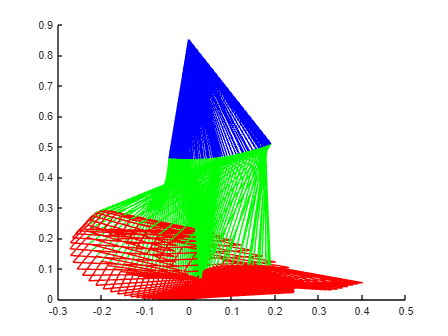

%Poses
x_knee = thighLength * sind(rHipPose);
y_knee = -thighLength * cosd(rHipPose);
x_ankle= x_knee + shankLength * sind(rKneePose);
y_ankle= y_knee - shankLength * cosd(rKneePose);
x_foot= x_ankle + footHeight * sind(rAnklePose);
y_foot= y_ankle - footHeight * cosd(rAnklePose);
x_toes= x_foot + (footLength-.0204*L) *sind(90 - rAnklePose);
y_toes= y_foot + (footLength-.0204*L) *cosd(90 - rAnklePose);
x_heel= x_foot - .0204*L *sind(90 - rAnklePose);
y_heel= y_foot - .0204*L *cosd(90 - rAnklePose);

%initial position

initialOffset = min(y_heel(:,1));

x_hip = zeros([1001,5]);
y_hip = zeros([1001,5]) - initialOffset;
y_knee = y_knee - initialOffset;
y_ankle= y_ankle - initialOffset;
y_foot= y_foot - initialOffset;
y_toes= y_toes - initialOffset;
y_heel= y_heel - initialOffset;

figure;
hold on;
yline(0,'k');

for i = 1:10:length(x_hip)
    plot([x_hip(i,1),x_knee(i,1)],[y_hip(i,1),y_knee(i,1)],'b');
    plot([x_knee(i,1),x_ankle(i,1)],[y_knee(i,1),y_ankle(i,1)],'g');
    plot([x_ankle(i,1),x_toes(i,1)],[y_ankle(i,1),y_toes(i,1)],'r');
    plot([x_ankle(i,1),x_heel(i,1)],[y_ankle(i,1),y_heel(i,1)],'r');
    plot([x_heel(i,1),x_toes(i,1)],[y_heel(i,1),y_toes(i,1)],'r');
    % plot([x_ankle(i),x_foot(i)],[y_ankle(i),y_foot(i)],'r');
    % plot([x_foot(i),x_toes(i)],[y_foot(i),y_toes(i)],'r');
    % plot([x_heel(i),x_foot(i)],[y_heel(i),y_foot(i)],'r');
    drawnow; %pause(.001);
    %axis([-0.5 0.5 -0.1 1]);
end

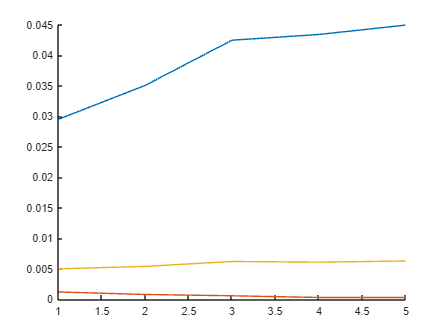


figure; hold on;
plot(y_toes(1,:));
plot(y_heel(1,:));
plot(y_foot(1,:));